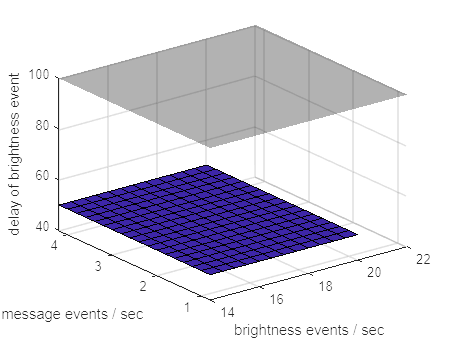

% Model A

ahRate = 14:0.5:22;
anRate = 0.8:0.2:4.2;
[delH, delN] = calculateDel(ahRate,anRate);
[ahConverted, anConverted] = ndgrid(ahRate, anRate); % ODER DOCH NDGRID??! meshgrid
A=zeros(length(ahRate), length(anRate))+100;
B=zeros(length(ahRate), length(anRate))+500;

figure(1)
surf(ahConverted, anConverted, delH);
hold on
%shading interp;
%colormap bone;
surf(ahConverted, anConverted, A, 'FaceColor','k', 'FaceAlpha',0.3, 'EdgeColor','none');
xlim([14,22]);
ylim([0.8,4.2]);
xlabel('brightness events / sec');
ylabel('message events / sec');
zlabel('delay of brightness event');
hold off
grid on

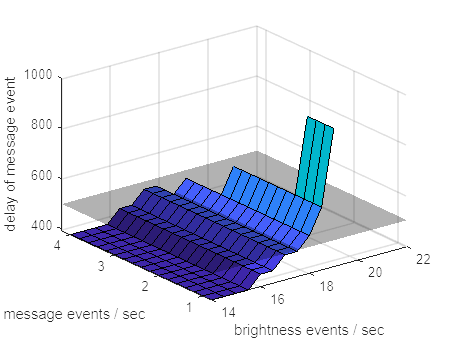


figure(1)
surf(ahConverted, anConverted, delN);
hold on
%shading interp;
%colormap bone;
surf(ahConverted, anConverted, B, 'FaceColor','k', 'FaceAlpha',0.3, 'EdgeColor','none');
xlim([14,22]);
ylim([0.8,4.2]);
xlabel('brightness events / sec');
ylabel('message events / sec');
zlabel('delay of message event');
hold off
grid on

%colormap summer;

function [delH, delN] = calculateDel(ahRate,anRate)
    b1_in = rtcfs(4);
    b2_in = rtctdma(8,10,10);
    b3_in = rtcfs(4);
    
    e1 = 200; % # instructions needed
    e2 = 1000;
    e3 = 160; % 20 * 8 bits need to be transfered using the bus
    e4 = 100;

    ah = 1000./ahRate;
    an = 1000./anRate;

    for i=1:length(ah)
        for j=1:length(an)
            aH_in = rtcpjd(ah(i), 0, 0);
            aN_in = rtcpjd(an(j), 0, 0);
            
            [~, b3_out1, del1, ~] = rtcgpc(aH_in, b3_in, e1);
            [aN_out1, ~, del2, ~] = rtcgpc(aN_in, b1_in, e2);
            [aN_out2, ~, del3, ~] = rtcgpc(aN_out1, b2_in, e3);
            [~, ~, del4, ~] = rtcgpc(aN_out2, b3_out1, e4);

            delayN = del2 + del3 + del4;
            %disp(['ahRate = ', num2str(ahRate(i))]);
            %disp(['anRate = ', num2str(anRate(j))]);
            %disp(['delay a_{Nachricht} = ', num2str(delayN)]);
    
            delH(i,j) = del1;
            delN(i,j) = delayN;
        end
    end
end